clear; clc;
fs = 44100;
one_beat = 0.4; 

% 定为C 大调
freqs = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, ...
         523.25, 587.33, 659.25, 698.46, 783.99, 880.00, 987.77, 1046.50];
scale_len = length(freqs);
total_notes = 32;

fprintf('正在生成 AR 音乐 (马尔可夫链)... \n');

正在生成 AR 音乐 (马尔可夫链)... 



ar_seq = zeros(1, total_notes);
ar_seq(1) = 8; 

for t = 2:total_notes
    prev = ar_seq(t-1);
    
    % 跳转概率 (高斯分布)
    steps = -4:4; 
    weights = exp(-steps.^2 / 2); 
    
    % 边界检查与归一化
    valid_indices = prev + steps;
    mask = (valid_indices >= 1) & (valid_indices <= scale_len);
    
    steps = steps(mask);
    weights = weights(mask);
    weights = weights / sum(weights); 
    
    % 随机选择
    r = rand;
    cum_w = cumsum(weights);
    idx = find(cum_w >= r, 1);
    ar_seq(t) = prev + steps(idx);
end

music_ar = synth_music(ar_seq, freqs, one_beat, fs);
audiowrite('AI_Music_AR_Flow.wav', music_ar, fs);
fprintf('-> 已保存: AI_Music_AR_Flow.wav\n\n');

-> 已保存: AI_Music_AR_Flow.wav




fprintf('正在生成 NAR 音乐 (随机噪声 + 规则修正)... \n');

正在生成 NAR 音乐 (随机噪声 + 规则修正)... 



nar_seq = randi(scale_len, 1, total_notes);

% 全局约束：强拍回归和弦
chord_tones = [1, 3, 5, 8, 10, 12, 15];

for t = 1:total_notes
    if mod(t, 4) == 1 
        % 强拍修正
        [~, min_idx] = min(abs(chord_tones - nar_seq(t)));
        nar_seq(t) = chord_tones(min_idx);
    else
        % 弱拍平滑
        if t > 1 && t < total_notes
            nar_seq(t) = round((nar_seq(t-1) + nar_seq(t+1))/2);
        end
    end
end
nar_seq = max(1, min(scale_len, nar_seq));

music_nar = synth_music(nar_seq, freqs, one_beat, fs);
audiowrite('AI_Music_NAR_Structure.wav', music_nar, fs);
fprintf('-> 已保存: AI_Music_NAR_Structure.wav\n\n');

-> 已保存: AI_Music_NAR_Structure.wav



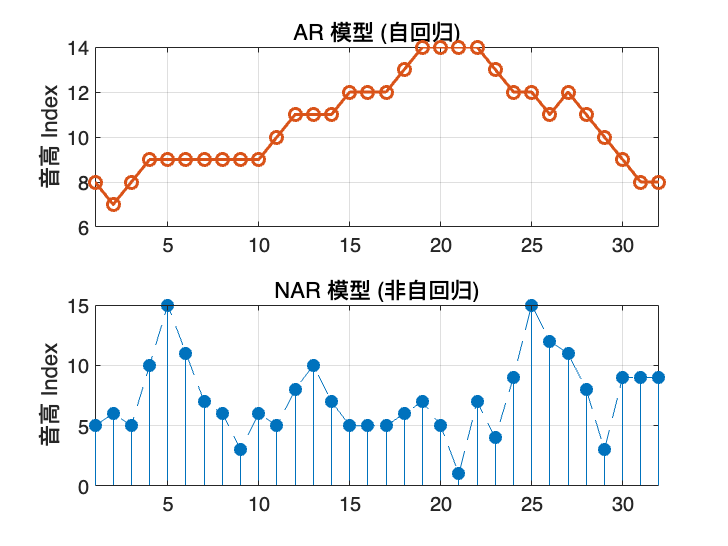

figure('Color', 'w');

t_axis = 1:total_notes;

subplot(2,1,1);
plot(t_axis, ar_seq, '-o', 'LineWidth', 1.5, 'Color', '#D95319');
title('AR 模型 (自回归)'); 
grid on; ylabel('音高 Index'); xlim([1 total_notes]);

subplot(2,1,2); 
stem(t_axis, nar_seq, 'filled', 'Color', '#0072BD');
hold on; plot(t_axis, nar_seq, '--', 'Color', '#0072BD');
title('NAR 模型 (非自回归)'); 
grid on; ylabel('音高 Index'); xlim([1 total_notes]);


fprintf('播放 AR 效果...\n');

播放 AR 效果...


sound(music_ar, fs);
pause(length(music_ar)/fs + 1);

fprintf('播放 NAR 效果...\n');

播放 NAR 效果...


sound(music_nar, fs);

function wave = synth_music(seq, freqs, one_beat, fs)
    wave = [];
    for i = 1:length(seq)
        f = freqs(seq(i));
        duration = one_beat;
        t = linspace(0, duration, round(duration*fs));
        y = sin(2*pi*f*t) + 0.5*sin(2*pi*2*f*t) + 0.2*sin(2*pi*3*f*t);
        env = exp(-4 * t / duration);
        
        wave = [wave, y .* env];
    end
    wave = wave / max(abs(wave));
end